%这是聚类分析代码
%按归档2012年(新版)为例,YearX导入5-51行,C-W列导入47*21矩阵数据

%test
%YearX=[1,2;3,4];

%YearX1=YearX.^2;
%Sum1=sum(YearX1,2);
%Sum2=Sum1.^0.5;
%YearX2=YearX./Sum2;
Yearto2012=((Year2012-min(Year2012,[],2))./(max(Year2012,[],2)-min(Year2012,[],2)));
Yearto2013=((Year2013-min(Year2013,[],2))./(max(Year2013,[],2)-min(Year2013,[],2)));
Yearto2014=((Year2014-min(Year2014,[],2))./(max(Year2014,[],2)-min(Year2014,[],2)));
Yearto2015=((Year2015-min(Year2015,[],2))./(max(Year2015,[],2)-min(Year2015,[],2)));
Yearto2016=((Year2016-min(Year2016,[],2))./(max(Year2016,[],2)-min(Year2016,[],2)));
Yearto2017=((Year2017-min(Year2017,[],2))./(max(Year2017,[],2)-min(Year2017,[],2)));
Yearto2018=((Year2018-min(Year2018,[],2))./(max(Year2018,[],2)-min(Year2018,[],2)));
Yearto2019=((Year2019-min(Year2019,[],2))./(max(Year2019,[],2)-min(Year2019,[],2)));
%0.78
[T2012,D2012]=dbscan(Yearto2012,0.73,1);
K2012=max(T2012);
SSE2012=0;
for k=1:K
    SSE2012=SSE2012+sum(D2012(T2012==k).^2);
end
SC2012=silhouette(Yearto2012,T2012);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2012=%f\n',SSE2012);

SSE2012=2.000000


fprintf('SC2012=%f\n',mean(SC2012));

SC2012=0.300708


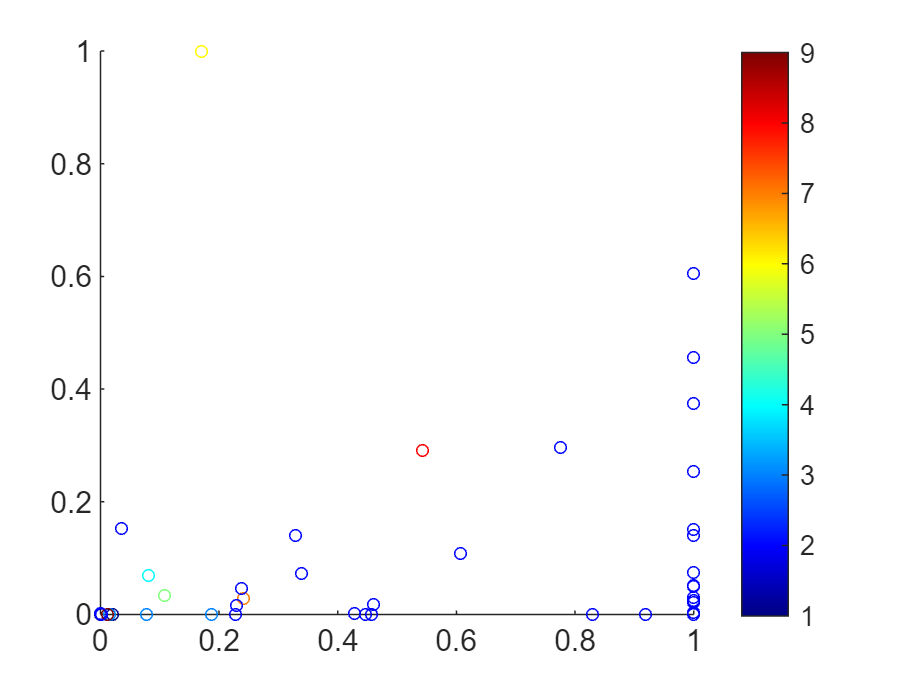

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2012(:,1), Yearto2012(:,2), 15, T2012);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2012,'complete');
% dendrogram(tree,0)
%0.78
[T2013,D2013]=dbscan(Yearto2013,0.73,1);
K2013=max(T2013);
SSE2013=0;
for k=1:K
    SSE2013=SSE2013+sum(D2013(T2013==k).^2);
end
SC2013=silhouette(Yearto2013,T2013);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2013=%f\n',SSE2013);

SSE2013=5.000000


fprintf('SC2013=%f\n',mean(SC2013));

SC2013=0.350359


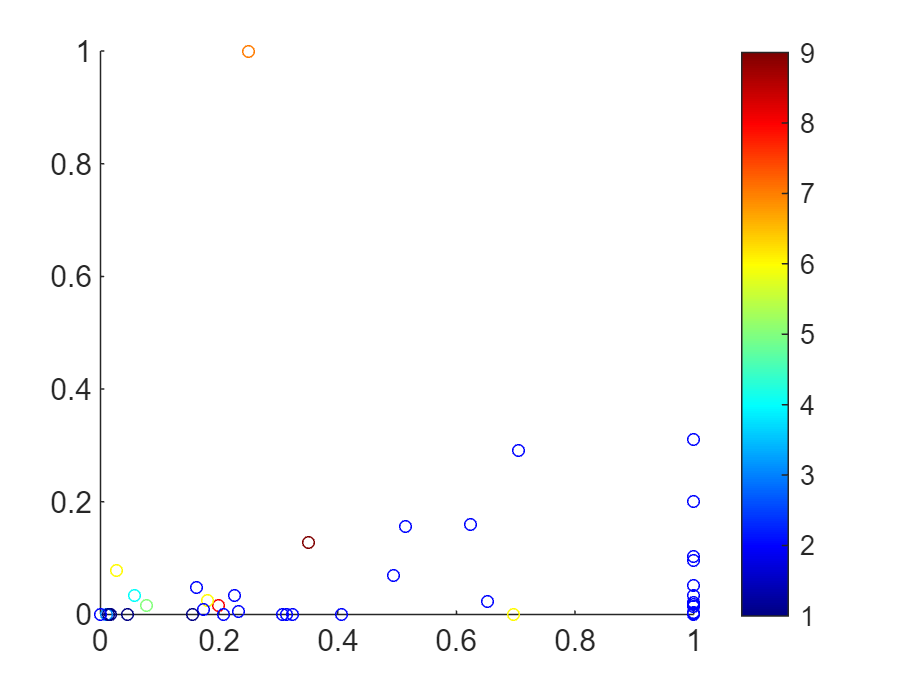

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2013(:,1), Yearto2013(:,2), 15, T2013);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2013,'complete');
% dendrogram(tree,0)
%0.89
[T2014,D2014]=dbscan(Yearto2014,0.8,1);
K2014=max(T2014);
SSE2014=0;
for k=1:K
    SSE2014=SSE2014+sum(D2014(T2014==k).^2);
end
SC2014=silhouette(Yearto2014,T2014);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2014=%f\n',SSE2014);

SSE2014=4.000000


fprintf('SC2014=%f\n',mean(SC2014));

SC2014=0.175517


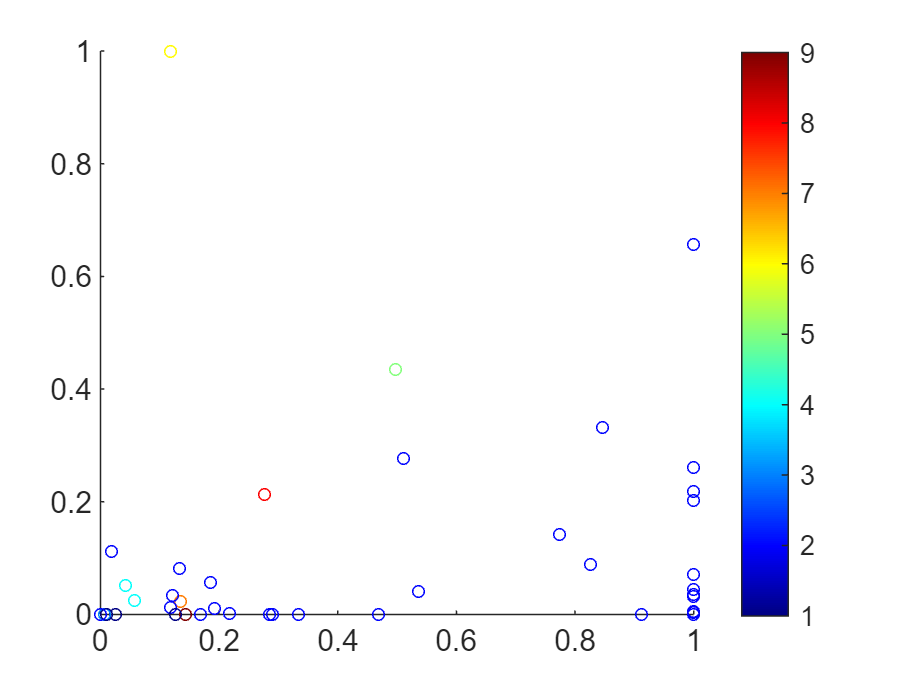

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2014(:,1), Yearto2014(:,2), 15, T2014);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2014,'complete');
% dendrogram(tree,0)
%0.945
[T2015,D2015]=dbscan(Yearto2015,0.9,1);
K2015=max(T2015);
SSE2015=0;
for k=1:K
    SSE2015=SSE2015+sum(D2015(T2015==k).^2);
end
SC2015=silhouette(Yearto2015,T2015);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2015=%f\n',SSE2015);

SSE2015=5.000000


fprintf('SC2015=%f\n',mean(SC2015));

SC2015=0.257971


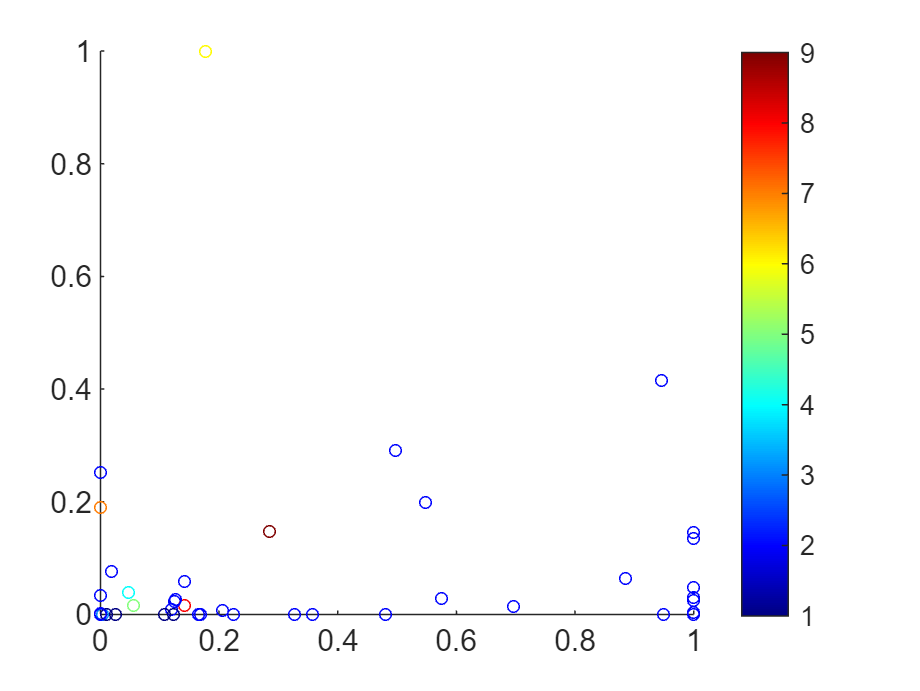

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2015(:,1), Yearto2015(:,2), 15, T2015);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2015,'complete');
% dendrogram(tree,0)
%2016 0.85 0.82 +0.63+
 [T2016,D2016]=dbscan(Yearto2016,0.63,1);
 K2016=max(T2016);
 SSE2016=0;
 for k=1:K
    SSE2016=SSE2016+sum(D2016(T2016==k).^2);
 end
 SC2016=silhouette(Yearto2016,T2016);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
 fprintf('SSE2016=%f\n',SSE2016);

SSE2016=5.000000


 fprintf('SC2016=%f\n',mean(SC2016));

SC2016=0.621597


 fprintf('r=%f\n',r);

r=0.010316


 fprintf('类数=%f\n',max(T2016))

类数=16.000000


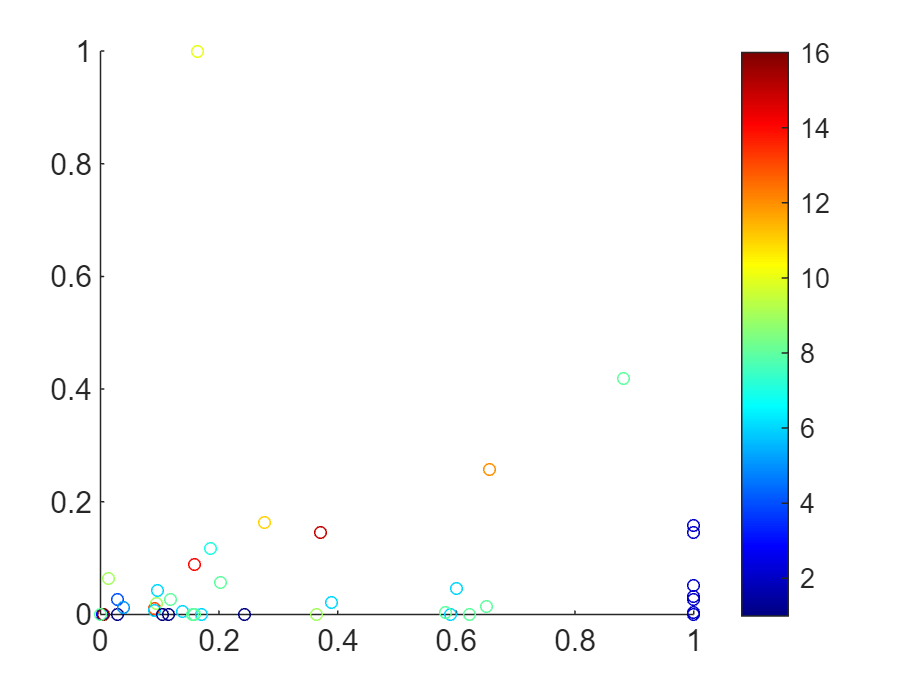

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
 scatter(Yearto2016(:,1), Yearto2016(:,2), 15, T2016);
 colormap(jet(256)); colorbar;

% tree=linkage(Yearto2016,'complete');
% dendrogram(tree,0)
% 计算每个簇的中心点
%  centers = zeros(max(T2016), size(Yearto2016,2));
%  for i=1:max(T2016)
%     centers(i,:) = mean(Yearto2016(T2016==i,:));
%  end
% 计算DBI指数
%  n = numel(T2016);
%  k = numel(unique(T2016));
%  S = zeros(k,1);
%  for i=1:k
%      S(i) = mean(pdist(Yearto2016(T2016==i,:)));
%  end
%  DB2016 = 0;
%  for i=1:k
%      max_val = -inf;
%      for j=1:k
%          if i~=j
%              val = (S(i) + S(j))/pdist([centers(i,:); centers(j,:)]);
%              if val>max_val
%              end
%          end
%      end
%      DB2016 = DB2016 + max_val;
%  end
%  DB2016 = DB2016/k;
% 显示DBI指数
%  fprintf('DBI index: %f\n', DB2016);
[T2017,D2017]=dbscan(Yearto2017,0.85,1);
K2017=max(T2017);
SSE2017=0;
for k=1:K
    SSE2017=SSE2017+sum(D2017(T2017==k).^2);
end
SC2017=silhouette(Yearto2017,T2017);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2017=%f\n',SSE2017);

SSE2017=5.000000


fprintf('SC2017=%f\n',mean(SC2017));

SC2017=0.341753


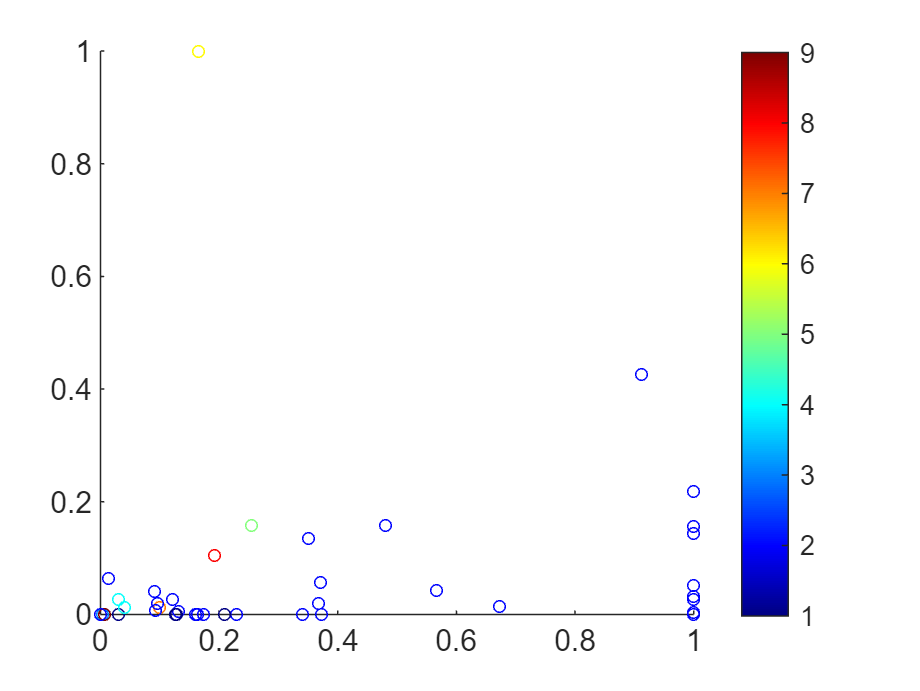

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2017(:,1), Yearto2017(:,2), 15, T2017);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2017,'complete');
% dendrogram(tree,0)
%0.78
[T2018,D2018]=dbscan(Yearto2018,0.665,1);
K2018=max(T2018);
SSE2018=0;
for k=1:K
    SSE2018=SSE2018+sum(D2018(T2018==k).^2);
end
SC2018=silhouette(Yearto2018,T2018);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2018=%f\n',SSE2018);

SSE2018=4.000000


fprintf('SC2018=%f\n',mean(SC2018));

SC2018=0.477955


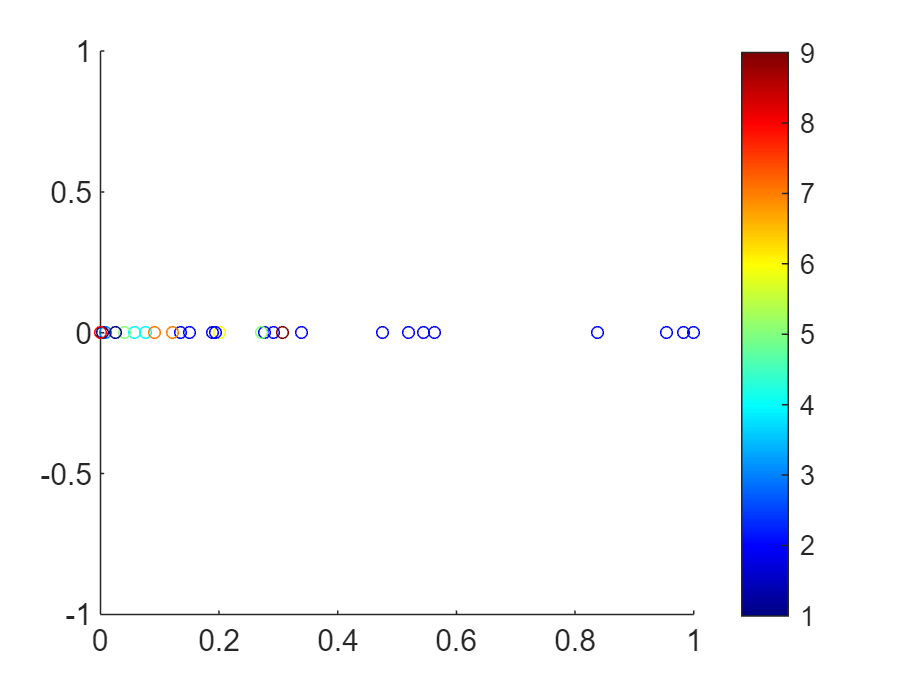

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2018(:,1), Yearto2018(:,2), 15, T2018);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2018,'complete');
% dendrogram(tree,0)
%0.78
[T2019,D2019]=dbscan(Yearto2019,0.675,1);
K2019=max(T2019);
SSE2019=0;
for k=1:K
    SSE2019=SSE2019+sum(D2019(T2019==k).^2);
end
SC2019=silhouette(Yearto2019,T2019);
% [~,~,CH2016]=clusterquality(Yearto2016,T2016);
% DB2016=db_index(Yearto2016,T2016);
fprintf('SSE2019=%f\n',SSE2019);

SSE2019=4.000000


fprintf('SC2019=%f\n',mean(SC2019));

SC2019=0.330623


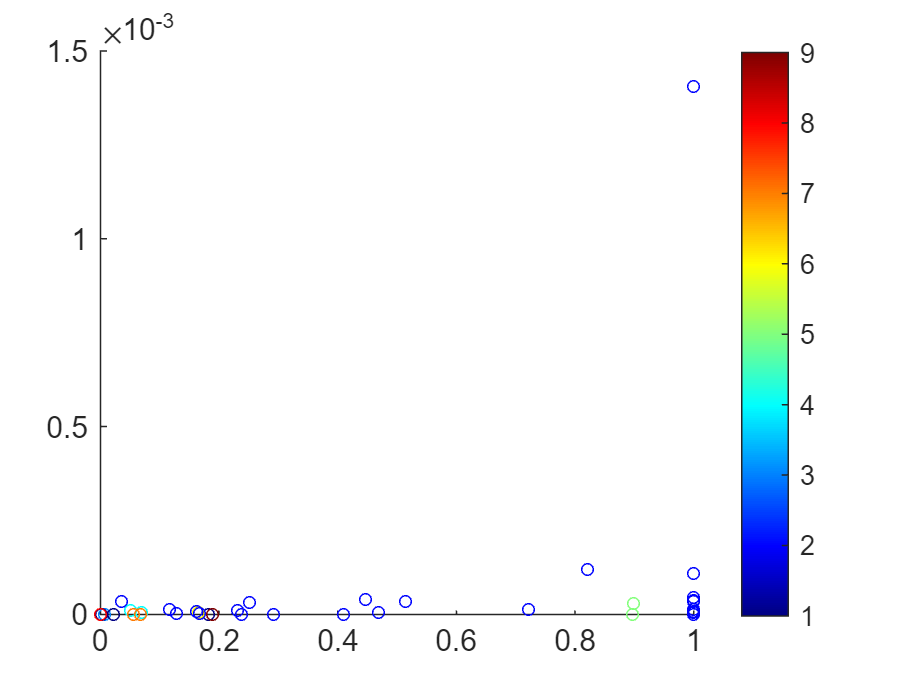

% fprintf('CH2016=%f\n',CH2016);
% fprintf('DBI2016=%f\n',DB2016);
% 将聚类结果可视化
scatter(Yearto2019(:,1), Yearto2019(:,2), 15, T2019);
colormap(jet(256)); colorbar;

% tree=linkage(Yearto2019,'complete');
% dendrogram(tree,0)
L=[2012,2013,2014,2015,2016,2017,2018,2019];
L1=[20.15,29.5, 22.5078, 23.16796, 23.51, 24.96768, 24.0015, 23.65589519];